%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ARSDK = readtimetable("AR SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSDKnoLK = readtimetable("AR SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSDKnoHg = readtimetable("AR SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ARSDKATEC = readtimetable("AR SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ARSDKATECnoLK = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ARSDKATECnoHg = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ARSDKEnt = readtimetable("AR SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ARSDKEntnoLK = readtimetable("AR SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ARSDKEntnoHg = readtimetable("AR SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");
ARSDKPicarro = readtimetable("AR SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

%STER
ARSTER = readtimetable("AR STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSTERnoLK = readtimetable("AR STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSTERnoHg = readtimetable("AR STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ARSSG = readtimetable("AR SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSSGnoLK = readtimetable("AR SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSSGnoHg = readtimetable("AR SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%%ppb data, including data with all flags
%SDK
ppbSDK = readtimetable("ppb SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSDKnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSDKnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKATEC = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ppbSDKATECnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ppbSDKATECnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKEnt = readtimetable("ppb SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ppbSDKEntnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ppbSDKEntnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");
ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

%STER
ppbSTER = readtimetable("ppb STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSTERnoLK = readtimetable("ppb STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSTERnoHg = readtimetable("ppb STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ppbSSG = readtimetable("ppb SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSSGnoLK = readtimetable("ppb SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSSGnoHg = readtimetable("ppb SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

cd ..

%SDK, AROMA
ppbAROMA = readtimetable("etoAROMA_SDK.xlsx");

%%receptors
points = readtable("mapPoints.xlsx", "sheet", "From Matlab"); %grab receptor data

%%met data
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
rawMetSTER = readtimetable("Met_STER.xlsx"); %STER 8/19-7/22
rawMetSSG = readtimetable("Met_SSG.xlsx"); %STER 8/19-7/22
rawMetHou = readtimetable("Met_houston.xlsx"); %Houston 9/22

cd ../.. %return to data folder

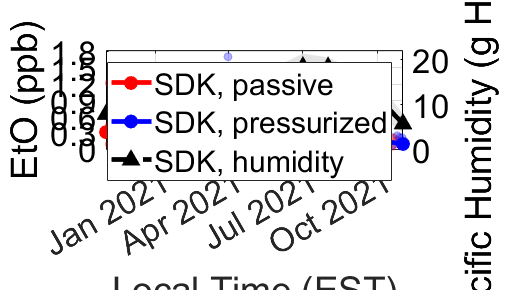

%%%%%%%%%%%%%%%%%%%%%%
%%%PLOT FIGURE 2
%%%%%%%%%%%%%%%%%%%%%%

fig = figure('Position', get(0, 'Screensize')); %for saving the figure

%%%a. Time Series
%%%INPUTS
dataSDKEnt = ppbSDKEnt;
dataSDKATEC = ppbSDKATEC;
dataSDKPicarro = ppbSDKPicarro;
dataSTER = ppbSTER;
dataSSG = ppbSSG;
colors = distinguishable_colors(7);
colorSTER = colors(5, :)/1.3;
colorSSG = [0.071, 0.74, 0.74];
colorAROMA = [0.8392, 0.5686, 0.3098];
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
colors = [1, 0, 0; 0, 0, 1; 0, 0, 0; colorAROMA; colorSTER; colorSSG];
xlims = datetime([2020, 2021], 11, 1);
xtickss = datetime(2021, 1, 1):calmonths(3):datetime(2022, 1, 1);
ylims = [-0.01, 1.81];
ytickss = 0:0.3:1.8;

%% dateshift all canister points to start of day
dataSDKEnt.time = dateshift(dataSDKEnt.time, "start", "day");
dataSDKATEC.time = dateshift(dataSDKATEC.time, "start", "day");

%%plot
ax = gca;
hold on
grid on
box on

hl = gobjects(3, 1);

%SDK, passive
dataMonthSDKEnt = binByMonth(dataSDKEnt); %upwind STER, bin by month
times = datenum(dataMonthSDKEnt.Properties.RowTimes); %grab date nums
[hl(1), hp] = boundedline(times, dataMonthSDKEnt.avgs, dataMonthSDKEnt.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(1, :));
hl(1).MarkerSize = 7; %change line aspects
hl(1).MarkerFaceColor = colors(1, :);
hl(1).LineWidth = 3.5;

for i = 1:size(dataSDKEnt, 2) %plot individual points, Entech
    s = scatter(datenum(dataSDKEnt.Properties.RowTimes), ...
        timetable2array(dataSDKEnt(:, i)), ...
        'o', 'MarkerFaceAlpha', 0.3, 'MarkerEdgeAlpha', 0.3, ...
        'MarkerFaceColor', colors(1, :), 'MarkerEdgeColor', colors(1, :));
end

%SDK, pressurized
dataSDKATEC.ATEC_ERG(116) = nan; %remove 1.71 ppb point
dataMonthSDKATEC = binByMonth(dataSDKATEC); %upwind STER, bin by month
times = datenum(dataMonthSDKATEC.Properties.RowTimes); %grab date nums
[hl(2), hp] = boundedline(times, dataMonthSDKATEC.avgs, dataMonthSDKATEC.stds, ...
    'o-', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(2, :));
hl(2).MarkerSize = 7; %change line aspects
hl(2).MarkerFaceColor = colors(2, :);
hl(2).LineWidth = 3.5;

for i = 1:size(dataSDKATEC, 2) %plot individual points, ATEC
    s = scatter(datenum(dataSDKATEC.Properties.RowTimes), ...
        timetable2array(dataSDKATEC(:, i)), ...
        'o', 'MarkerFaceAlpha', 0.3, 'MarkerEdgeAlpha', 0.3, ...
        'MarkerFaceColor', colors(2, :), 'MarkerEdgeColor', colors(2, :));
end

yyaxis right
%SDK, humidity
dataMonthHumid = binByMonth(rawMetSDK(:, 7)); %upwind STER, bin by month
times = datenum(dataMonthHumid.Properties.RowTimes); %grab date nums
[hl(3), hp] = boundedline(times, dataMonthHumid.avgs, dataMonthHumid.stds, ...
    '^--', 'nan', 'gap', 'alpha', 'transparency', 0.1, 'color', colors(3, :));
hl(3).MarkerSize = 7; %change line aspects
hl(3).MarkerFaceColor = colors(3, :);
hl(3).LineWidth = 3.5;

% %move lines to top
% uistack(hl(1), 'top')
% uistack(hl(2), 'top')

%%lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "mmm yyyy");
yyaxis left
ylim(ylims)
yticks(ytickss)
yyaxis right %humidity axis
ax.YColor = 'k';

%%labels
pbaspect([3, 1, 1])
ax.FontSize = 25;
xlabel("Local Time (EST)")
yyaxis left
ylabel("EtO (ppb)")
yyaxis right
ylabel("Specific Humidity (g H_2O/kg air)", "Interpreter", "tex")
legend(hl(:), "SDK, passive", "SDK, pressurized", "SDK, humidity")

hold off

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Figure supplemental humidity TO-15.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data